THIS FILE CONTAINS THE TESTS FOR SOME ENVIRONMENTS IN DIFFERENT SECTIONS AGAINST  AGENTS


clear all;
close all;

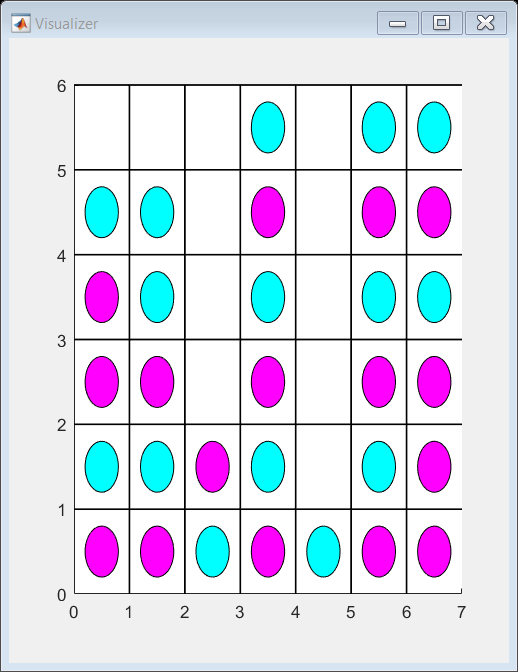


% AGENT vs AGENT for env 1 and 2
agent_1= load("DQN/savedAgents/Env2_defaultNet_LearnRate0001_Entropy09.mat","agent");
agent1= agent_1.agent;
agent_2= load("DQN/savedAgents/Env2_defaultNet_LearnRate0001_Entropy09.mat","agent");
agent2= agent_2.agent;

num_episodes = 100;

agent1_wins = 0;
agent2_wins = 0;
draws = 0;

for episode = 1:num_episodes

    env     = Environment_1_2_agent;
    obsInfo = env.getObservationInfo;
    actInfo = env.getActionInfo;
    numObs  = obsInfo.Dimension(1);
    numAct  = numel(actInfo);

    plot(env)

    obs = zeros([42 1]);  % Set initial state

    termination_condition=false;

    while ~termination_condition

        reward1=0;
        reward2=0;

        % Agent 1's action
        [action_agent1, agent1] = getAction(agent1, obs);
        action_agent1 = action_agent1{1};  % Extract the integer value

        % Apply agent 1's action to the environment
        [obs, reward1, termination_condition, LoggedSignals] = env.step(action_agent1, 1);
        
        if ~termination_condition
            % Agent 2's action
            action_agent2 = getAction(agent2, obs);
            action_agent2 = action_agent2{1};  % Extract the integer value
            
            % Apply agent 2's action to the environment
            [obs, reward2, termination_condition] = env.step(action_agent2, 9);
        end
        
    end

    % Determine the winner and update the win/loss/draw counters
    if reward1 >= 0.9
        agent1_wins = agent1_wins + 1;
    elseif reward2 >= 0.9
        agent2_wins = agent2_wins + 1;
    else
        draws = draws + 1;
    end
    
end


fprintf('Agent 1 wins: %d\n', agent1_wins/num_episodes*100);

Agent 1 wins: 30


fprintf('Agent 2 wins: %d\n', agent2_wins/num_episodes*100);

Agent 2 wins: 70


fprintf('Draws: %d\n', draws/num_episodes*100);

Draws: 0


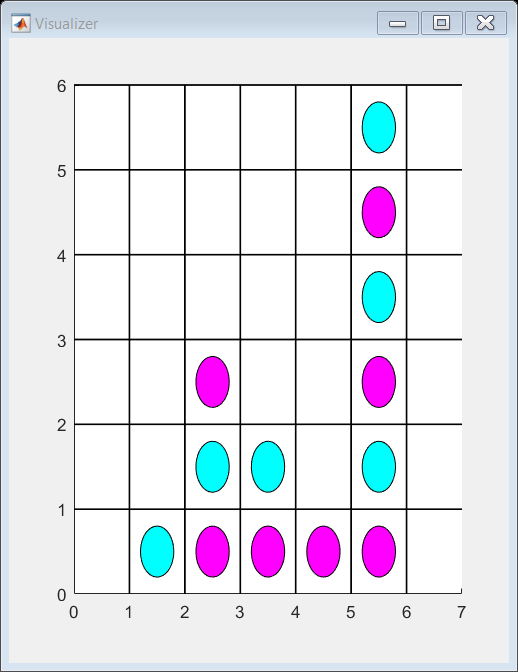



% AGENT vs AGENT for env 3 and 4
agent_1= load("DQN/savedAgents/Env3_defaultNet_LearnRate0001_Entropy09.mat","agent");
agent1= agent_1.agent;
agent_2= load("DQN/savedAgents/Env3_defaultNet_LearnRate0001_Entropy09.mat","agent");
agent2= agent_2.agent;

num_episodes = 100;

agent1_wins = 0;
agent2_wins = 0;
draws = 0;

for episode = 1:num_episodes

    env     = Environment_3_4_agent;
    obsInfo = env.getObservationInfo;
    actInfo = env.getActionInfo;
    numObs  = obsInfo.Dimension(1);
    numAct  = numel(actInfo);

    plot(env)

    obs = zeros([42 1]);  % Set initial state

    termination_condition=false;

    while ~termination_condition

        reward1=0;
        reward2=0;

        % Agent 1's action
        [action_agent1, agent1] = getAction(agent1, obs);
        action_agent1 = action_agent1{1};  % Extract the integer value

        % Apply agent 1's action to the environment
        [obs, reward1, termination_condition, LoggedSignals] = env.step(action_agent1, 1);
        
        if ~termination_condition
            % Agent 2's action
            action_agent2 = getAction(agent2, obs);
            action_agent2 = action_agent2{1};  % Extract the integer value
            
            % Apply agent 2's action to the environment
            [obs, reward2, termination_condition] = env.step(action_agent2, 9);
        end
        
    end

    % Determine the winner and update the win/loss/draw counters
    if reward1 == 1
        agent1_wins = agent1_wins + 1;
    elseif reward1 == -0.5
        agent2_wins = agent2_wins + 1;
    elseif reward2 >= 0.9
        agent2_wins = agent2_wins + 1;
    elseif reward2 == -0.5
        agent1_wins = agent1_wins + 1;
    else
        draws = draws + 1;
    end
    
end


fprintf('Agent 1 wins: %d\n', agent1_wins/num_episodes*100);

Agent 1 wins: 100


fprintf('Agent 2 wins: %d\n', agent2_wins/num_episodes*100);

Agent 2 wins: 0


fprintf('Draws: %d\n', draws/num_episodes*100);

Draws: 0
